clear

aceleracaoMedida = readmatrix("dados/acelerometroMedido.csv");
aceleracaoReal = readmatrix("dados/acelerometroReal.csv");

velocidadeMedida = readmatrix("dados/velocidadeMedida.csv");
velocidadeReal = readmatrix("dados/velocidadeReal.csv");

posicaoMedida = readmatrix("dados/posicaoMedida.csv");
posicaoReal = readmatrix("dados/posicaoReal.csv");

dadosKalman = readmatrix("dados/dadosKalman.csv");
aceleracaoDadosKalman = rmmissing(readmatrix("dados/aceleracaoDadosKalman.csv")');
velocidadeDadosKalman = rmmissing(readmatrix("dados/velocidadeDadosKalman.csv")');
posicaoDadosKalman = rmmissing(readmatrix("dados/posicaoDadosKalman.csv")');


intervalo = 1:860;
dt = 0.05;
t = 0:dt:length(intervalo)*dt - dt;

aceleracaoMedida = aceleracaoMedida(:,intervalo);
aceleracaoReal = aceleracaoReal(:,intervalo);

velocidadeMedida = velocidadeMedida(:,intervalo);
velocidadeReal = velocidadeReal(:,intervalo);

posicaoMedida = posicaoMedida(:,intervalo) - posicaoMedida(:,1);
posicaoReal = posicaoReal(:,intervalo) - posicaoReal(:,1);

dadosKalman = dadosKalman(:,intervalo);

# Dados Acelerômetro

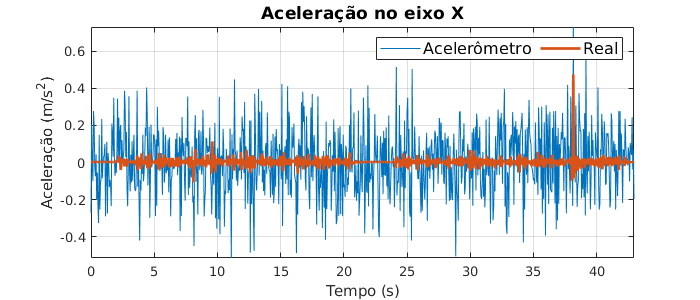

figure('Position', [0 0 700 300]); clf;
p = plot(t, aceleracaoMedida(1,:), t, aceleracaoReal(1,:));
p(1).LineWidth = 0.5;
p(2).LineWidth = 2;
legend('Acelerômetro','Real','Location',"northeast",'FontSize',12, "NumColumns",2)
title('Aceleração no eixo X','FontSize',13)
xlabel('Tempo (s)')
ylabel('Aceleração (m/s^2)')
axis tight
grid on

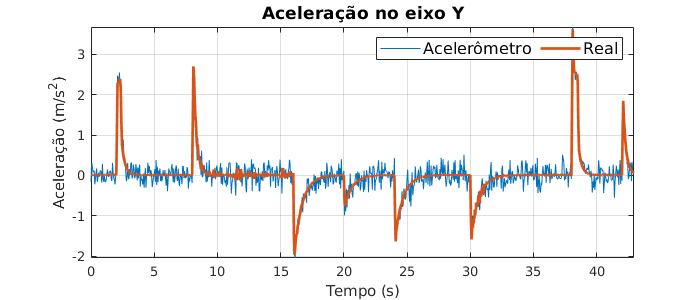

figure('Position', [0 0 700 300]); clf;
p = plot(t, aceleracaoMedida(2,:), t, aceleracaoReal(2,:));
p(1).LineWidth = 0.5;
p(2).LineWidth = 2;
legend('Acelerômetro','Real','Location',"northeast",'FontSize',12, "NumColumns",2)
title('Aceleração no eixo Y','FontSize',13)
xlabel('Tempo (s)')
ylabel('Aceleração (m/s^2)')
axis tight
grid on

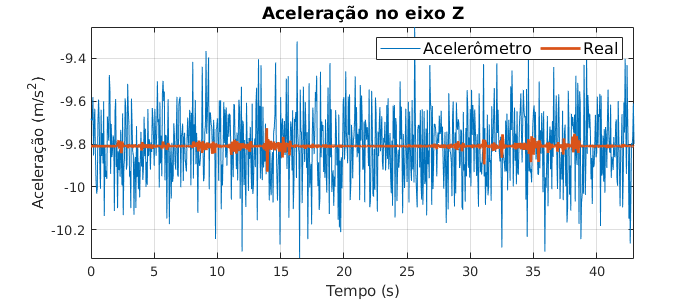

figure('Position', [0 0 700 300]); clf;
p = plot(t, aceleracaoMedida(3,:), t, aceleracaoReal(3,:));
p(1).LineWidth = 0.5;
p(2).LineWidth = 2;
legend('Acelerômetro','Real','Location',"northeast",'FontSize',12, "NumColumns",2)
title('Aceleração no eixo Z','FontSize',13)
xlabel('Tempo (s)')
ylabel('Aceleração (m/s^2)')
axis tight
grid on

# Dados Velocidade

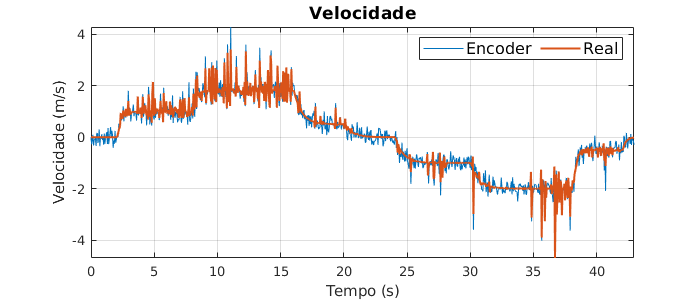



figure('Position', [0 0 700 300]); clf;
p = plot(t, velocidadeMedida(1,:), t, velocidadeReal(1,:));
p(1).LineWidth = 0.5;
p(2).LineWidth = 1.5;
legend('Encoder','Real','Location',"northeast",'FontSize',12, "NumColumns",2)
title('Velocidade','FontSize',13)
xlabel('Tempo (s)')
ylabel('Velocidade (m/s)')
axis tight
grid on

# Dados GPS

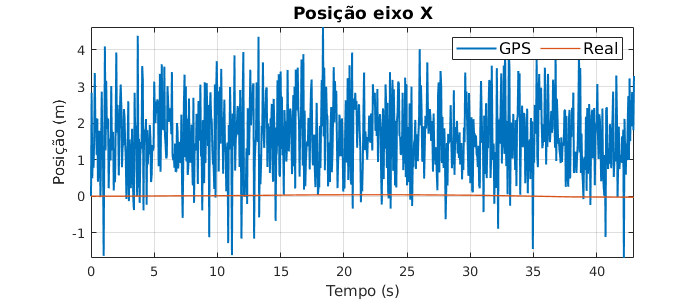

figure('Position', [0 0 700 300]); clf;
p = plot(t, posicaoMedida(1,:), t, posicaoReal(1,:));
p(1).LineWidth = 1.5;
p(2).LineWidth = 1;
legend('GPS','Real','Location',"northeast","FontSize",12, "NumColumns",2)
title('Posição eixo X','FontSize',13)
xlabel('Tempo (s)')
ylabel('Posição (m)')
axis tight
grid on

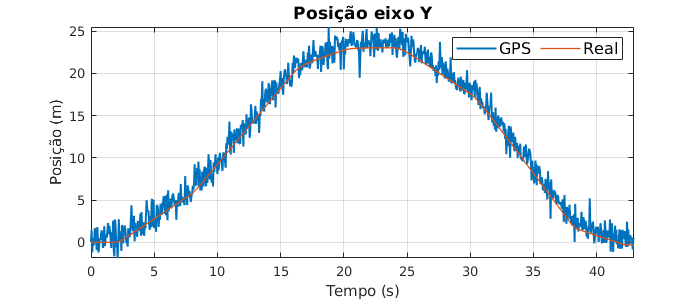


figure('Position', [0 0 700 300]); clf;
p = plot(t, posicaoMedida(2,:),t, posicaoReal(2,:));
p(1).LineWidth = 1.5;
p(2).LineWidth = 1;
legend('GPS','Real','Location',"northeast",'FontSize',12, "NumColumns",2)
title('Posição eixo Y','FontSize',13)
xlabel('Tempo (s)')
ylabel('Posição (m)')
axis tight
grid on

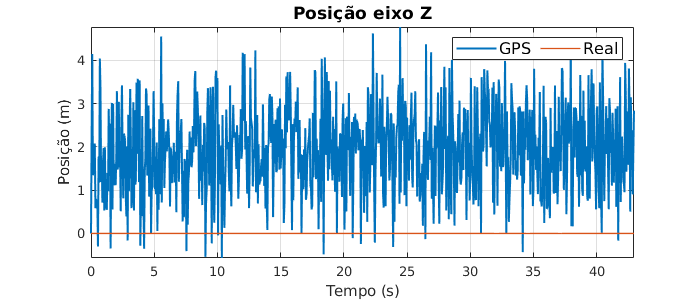


figure('Position', [0 0 700 300]); clf;
p = plot(t, posicaoMedida(3,:),t, posicaoReal(3,:));
p(1).LineWidth = 1.5;
p(2).LineWidth = 1;
legend('GPS','Real','Location',"northeast",'FontSize',12, "NumColumns",2)
title('Posição eixo Z','FontSize',13)
xlabel('Tempo (s)')
ylabel('Posição (m)')
axis tight
grid on

# Dados Kalman

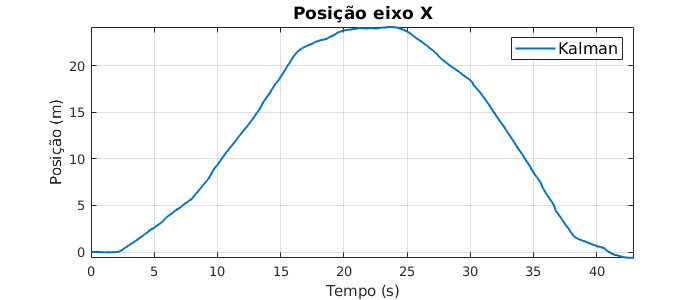

figure('Position', [0 0 700 300]); clf;
p = plot(t, dadosKalman(1,:));
p(1).LineWidth = 1.5;
legend('Kalman','Location',"northeast","FontSize",12, "NumColumns",2)
title('Posição eixo X','FontSize',13)
xlabel('Tempo (s)')
ylabel('Posição (m)')
axis tight
grid on

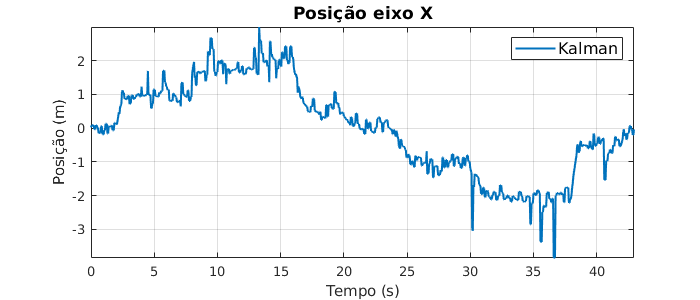


figure('Position', [0 0 700 300]); clf;
p = plot(t, dadosKalman(2,:));
p(1).LineWidth = 1.5;
legend('Kalman','Location',"northeast","FontSize",12, "NumColumns",2)
title('Posição eixo X','FontSize',13)
xlabel('Tempo (s)')
ylabel('Posição (m)')
axis tight
grid on

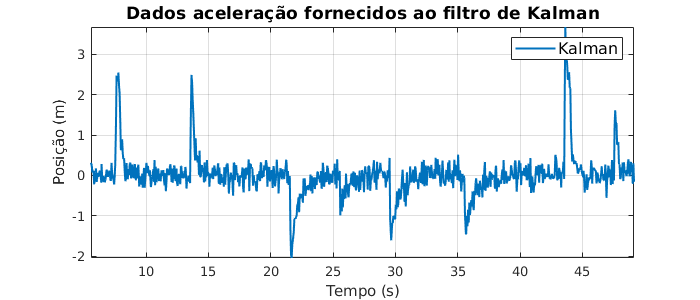


figure('Position', [0 0 700 300]); clf;
p = plot(aceleracaoDadosKalman(:,2),aceleracaoDadosKalman(:,1));
p(1).LineWidth = 1.5;
legend('Kalman','Location',"northeast","FontSize",12, "NumColumns",2)
title('Dados aceleração fornecidos ao filtro de Kalman','FontSize',13)
xlabel('Tempo (s)')
ylabel('Posição (m)')
axis tight
grid on

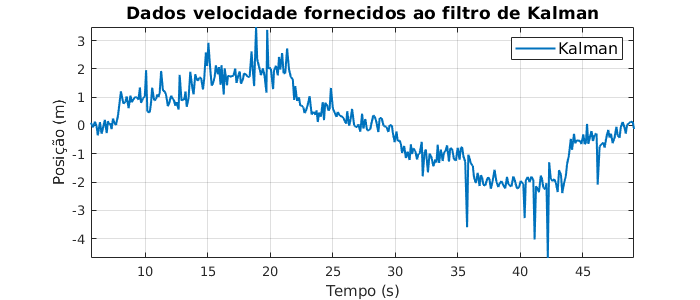


figure('Position', [0 0 700 300]); clf;
p = plot(velocidadeDadosKalman(:,2),velocidadeDadosKalman(:,1));
p(1).LineWidth = 1.5;
legend('Kalman','Location',"northeast","FontSize",12, "NumColumns",2)
title('Dados velocidade fornecidos ao filtro de Kalman','FontSize',13)
xlabel('Tempo (s)')
ylabel('Posição (m)')
axis tight
grid on

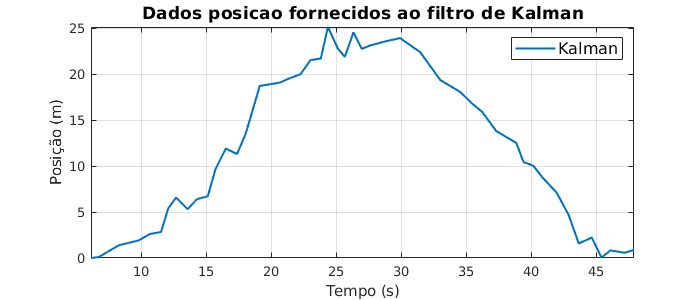


figure('Position', [0 0 700 300]); clf;
p = plot(posicaoDadosKalman(:,2),posicaoDadosKalman(:,1));
p(1).LineWidth = 1.5;
legend('Kalman','Location',"northeast","FontSize",12, "NumColumns",2)
title('Dados posicao fornecidos ao filtro de Kalman','FontSize',13)
xlabel('Tempo (s)')
ylabel('Posição (m)')
axis tight
grid on

# Filtro Kalman real Matlab

% Espaço de estados do sistema acelerado
A = [1 dt; 0 1];
B = [0.5*dt^2; dt];

% Dados utilizado no filtro de Kalman
dadosAceleracao = readmatrix("dados/aceleracaoDadosKalman.csv");
dadosAceleracao = dadosAceleracao(1,:);
dadosVelocidade = readmatrix("dados/velocidadeDadosKalman.csv");
dadosVelocidade = dadosVelocidade(1,:);
dadosPosicao = readmatrix("dados/posicaoDadosKalman.csv");
dadosPosicao = dadosPosicao(1,:);
posicao =  posicaoReal;

% Agorítmo do Filtro Kalman
Xcorrigido = zeros(2, length(intervalo));

rAceleracao = 2.5;
P = [0.5*dt^2*rAceleracao 0; 0 dt*rAceleracao];
Pcorrigido = P;

rv = 0.15;
rgps = 0.55;
R = [rgps 0; 0 rv];
Rv = [0 0; 0 rv];
Rgps = [rgps 0; 0 0];
H = eye(2,2);

for i=2:length(dadosKalman)
    Xprevisto = A*Xcorrigido(:,i-1) + B*dadosAceleracao(i-1); % Valor previsto a priori
    Pprevisto = A*Pcorrigido*A.' + P; % Erro previsto a priori
    
    KG = 0;
    Y = 0;
    if(isnan(dadosVelocidade(i-1)) && isnan(dadosPosicao(i-1)))
        KG = 0;
        Y = Xprevisto;
    elseif(isnan(dadosVelocidade(i-1)))
        KG = (Pprevisto*H.')/(H*Pprevisto*H.' + Rgps);
        Y = [dadosPosicao(i-1); Xprevisto(2)];
    elseif(isnan(dadosPosicao(i-1)))
        KG = (Pprevisto*H.')/(H*Pprevisto*H.' + Rv);
        Y= [Xprevisto(1); dadosVelocidade(i-1)];
    else
        KG = (Pprevisto*H.')/(H*Pprevisto*H.' + R);
        Y= [dadosPosicao(i-1); dadosVelocidade(i-1)];
    end

    Xcorrigido(:,i) = Xprevisto + KG*(Y - H*Xprevisto); % Valor previsto a posteriori
    Pcorrigido = Pprevisto - KG*H*Pprevisto; % Erro do valor a posteriori

end

sqrt(mean((Xcorrigido(1,:) - posicao(2,:)).^2))

ans = 0.6478

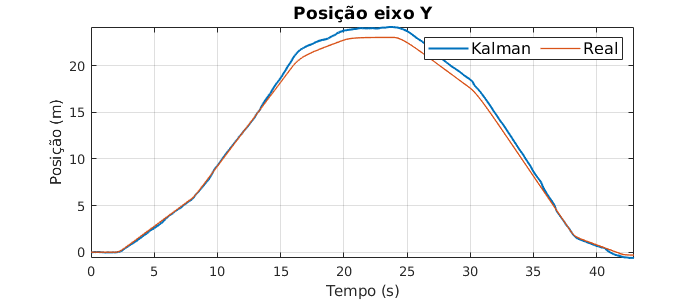



figure('Position', [0 0 700 300]); clf;
p = plot(t, Xcorrigido(1,:), t, posicao(2,:));
p(1).LineWidth = 1.5;
p(2).LineWidth = 1;
legend('Kalman','Real','Location',"northeast",'FontSize',12, "NumColumns",2)
title('Posição eixo Y','FontSize',13)
xlabel('Tempo (s)')
ylabel('Posição (m)')
axis tight
grid on

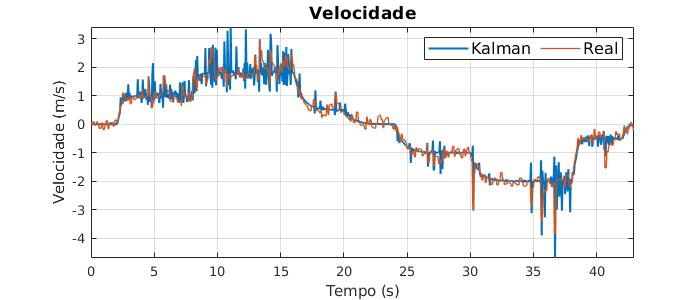

figure('Position', [0 0 700 300]); clf;
p = plot(t, velocidadeReal(1,intervalo), t, Xcorrigido(2,:));
p(1).LineWidth = 1.5;
p(2).LineWidth = 1;
legend('Kalman','Real','Location',"northeast",'FontSize',12, "NumColumns",2)
title('Velocidade','FontSize',13)
xlabel('Tempo (s)')
ylabel('Velocidade (m/s)')
axis tight
grid on